# Method of Moments

## Notes

This solution relies heavily on the maximum likelihood solution, especially for the Probit standard error Monte Carlo.

This solution first shows a simple example, and then wraps it in a loop to perform the Monte Carlo.

## Setup

Clear and reset the workspace and load required data

% Clean up everything
clear all
close all
clc
% Reset rng to make runs the same
rng('default')
% Load the data
load SP_FTSE

## S&P 500

This solution answers questions 1 - 4 for the S&P 500 and then for the FTSE 100. This produces a simpler solution.

## Returns

Here I use 100 x returns which are nicer to look at than actual returns. The method of moment estiamtors are implemented directly from the notes.

% 100 x returns
r = 100 * diff(log(SP500_monthly(:,3)));
% First four moments, and transformation to get skewness and kurtotis
mu = mean(r)

mu = 0.6010

sigma2 = mean((r-mu).^2)

sigma2 = 17.6671

mom3 = mean((r-mu).^3);
skewness = mom3/sigma2^(3/2)

skewness = -0.6606

mom4 = mean((r-mu).^4);
kurtosis = mom4/sigma2^2

kurtosis = 5.4163

## Covariance estimation

Here I use compute the moment errors for the mean and the variance. Since these conditions are linear in the moments I am interested in, the Jacobian is just an identity matrix and so it doesn't appear.

u1 = r - mu;
u2 = (r - mu).^2 - sigma2;
u = [u1 u2];
T = length(r);
% This is the cov that appears in the sqrt(T)(theta-hat - theta_0) version
% of the CLT
acov = u'*u / T

acov =    1.0e+03 *

    0.0177   -0.0491
   -0.0491    1.3784


% This is the covariance uses for inference, ntoe the divide by T
cov_for_inverence = acov / T

cov_for_inverence =     0.0231   -0.0642
   -0.0642    1.8042


% The standard error is just the square root of the parameter variances
stderr = sqrt(diag(cov_for_inverence))

stderr =     0.1521
    1.3432


## Sharpe ratio

The sharpe ratio is the ratio of the mean to the standard deviation. The delta method is used to compute the covariance of the Sharpe ratio

SR = mu/sqrt(sigma2)

SR = 0.1430

% Derivative matrix of the non-linear function w.r.t. parameters
D = [sigma2^(-1/2) -1/2*mu*sigma2^(-3/2)];
% Asymptotic covariance
SR_acov = D*acov*D'

SR_acov = 1.1170

% Divide by T for inference
SR_cov_for_inference = SR_acov/T

SR_cov_for_inference = 0.0015

% Standard error
SR_stderr = sqrt(diag(SR_cov_for_inference))

SR_stderr = 0.0382

SR_tstat = SR/SR_stderr

SR_tstat = 3.7392

## Moving windows

Moving windows are simple graphical tools to examine estimators for stability. This code uses the same moment estimators are in the first part of the solution. subplot is used to graph the data.

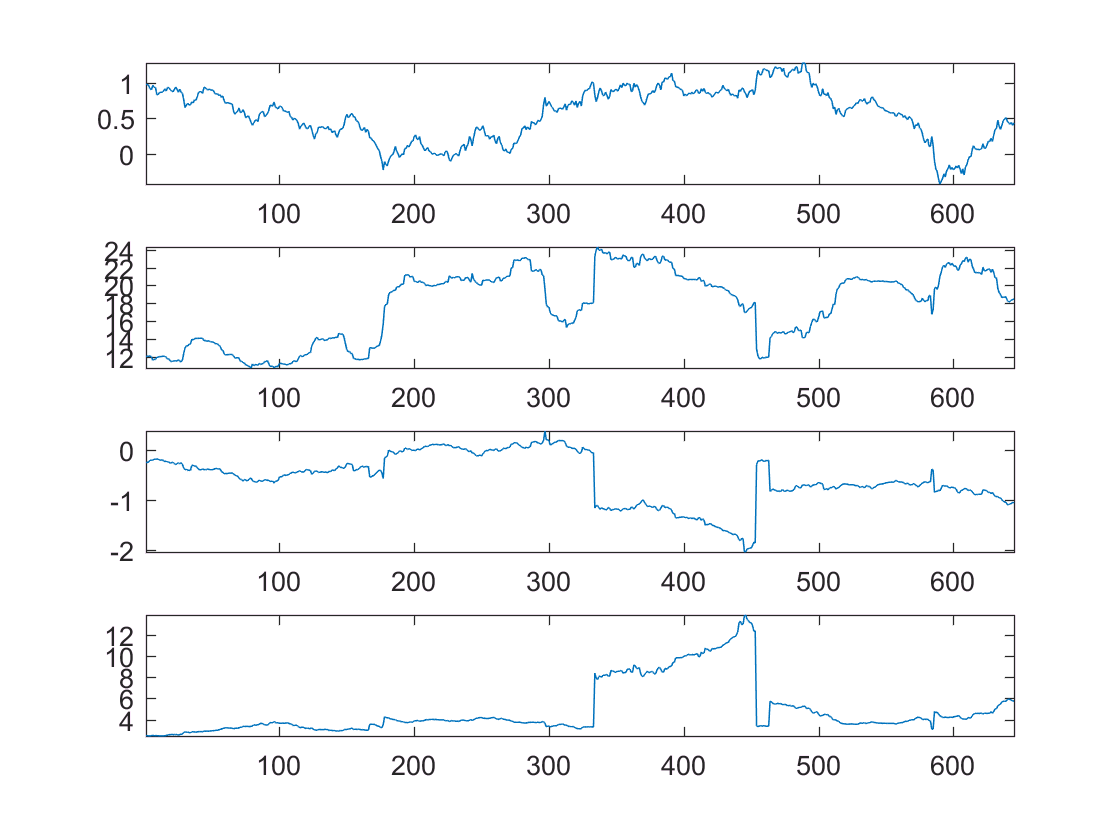

% Relabel returns so I can use r in the loop
returns = r;
% Initialize somewhere to store the estimates
mus = zeros(T-119,1);
sigma2s = zeros(T-119,1);
skewnesses = zeros(T-119,1);
kurtoses = zeros(T-119,1);
% Use a loop to estimate the parameters
for i=1:T-119
    r = returns(i:i+119);
    mus(i) = mean(r);
    sigma2s(i) = mean((r-mus(i)).^2);
    mom3 = mean((r-mus(i)).^3);
    skewnesses(i) = mom3/sigma2s(i)^(3/2);
    mom4 = mean((r-mus(i)).^4);
    kurtoses(i) = mom4/sigma2s(i)^2;
end
% Form into a matrix
data = [mus sigma2s skewnesses kurtoses];
% Open a new figure
figure(1)
% Loop over data and use subplot to graph
for i=1:4
    subplot(4,1,i)
    plot(data(:,i))
    axis tight
end

## FTSE 100

The remainder presents the results for the FTSE. Note the differences in teh kurtosis, Sharpe ratio and the standard errors

## Returns

Here I use 100 x returns which are nicer to look at than actual returns. The method of moment estiamtors are implemented directly from the notes.

% 100 x returns
r = 100 * diff(log(FTSE100_monthly(:,3)));

% First four moments, and transformation to get skewness and kurtotis
mu = mean(r)

mu = 0.4919

sigma2 = mean((r-mu).^2)

sigma2 = 21.4474

mom3 = mean((r-mu).^3);
skewness = mom3/sigma2^(3/2)

skewness = -1.1426

mom4 = mean((r-mu).^4);
kurtosis = mom4/sigma2^2

kurtosis = 8.0658

## Covariance estimation

Here I use compute the moment errors for the mean and the variance. Since these conditions are linear in the moments I am interested in, the Jacobian is just an identity matrix and so it doesn't appear.

u1 = r - mu;
u2 = (r - mu).^2 - sigma2;
u = [u1 u2];
T = length(r);
% This is the cov that appears in the sqrt(T)(theta-hat - theta_0) version
% of the CLT
acov = u'*u / T

acov =    1.0e+03 *

    0.0214   -0.1135
   -0.1135    3.2502


% This is the covariance uses for inference, ntoe the divide by T
cov_for_inverence = acov / T

cov_for_inverence =     0.0608   -0.3215
   -0.3215    9.2073


% The standard error is just the square root of the parameter variances
stderr = sqrt(diag(cov_for_inverence))

stderr =     0.2465
    3.0344


## Sharpe ratio

The sharpe ratio is the ratio of the mean to the standard deviation. The delta method is used to compute the covariance of the Sharpe ratio

SR = mu/sqrt(sigma2)

SR = 0.1062

% Derivative matrix of the non-linear function w.r.t. parameters
D = [sigma2^(-1/2) -1/2*mu*sigma2^(-3/2)];
% Asymptotic covariance
SR_acov = D*acov*D'

SR_acov = 1.1413

% Divide by T for inference
SR_cov_for_inference = SR_acov/T

SR_cov_for_inference = 0.0032

% Standard error
SR_stderr = sqrt(diag(SR_cov_for_inference))

SR_stderr = 0.0569

SR_tstat = SR/SR_stderr

SR_tstat = 1.8680

## Moving windows

Moving windows are simple graphical tools to examine estimators for stability. This code uses the same moment estimators are in the first part of the solution. subplot is used to graph the data.

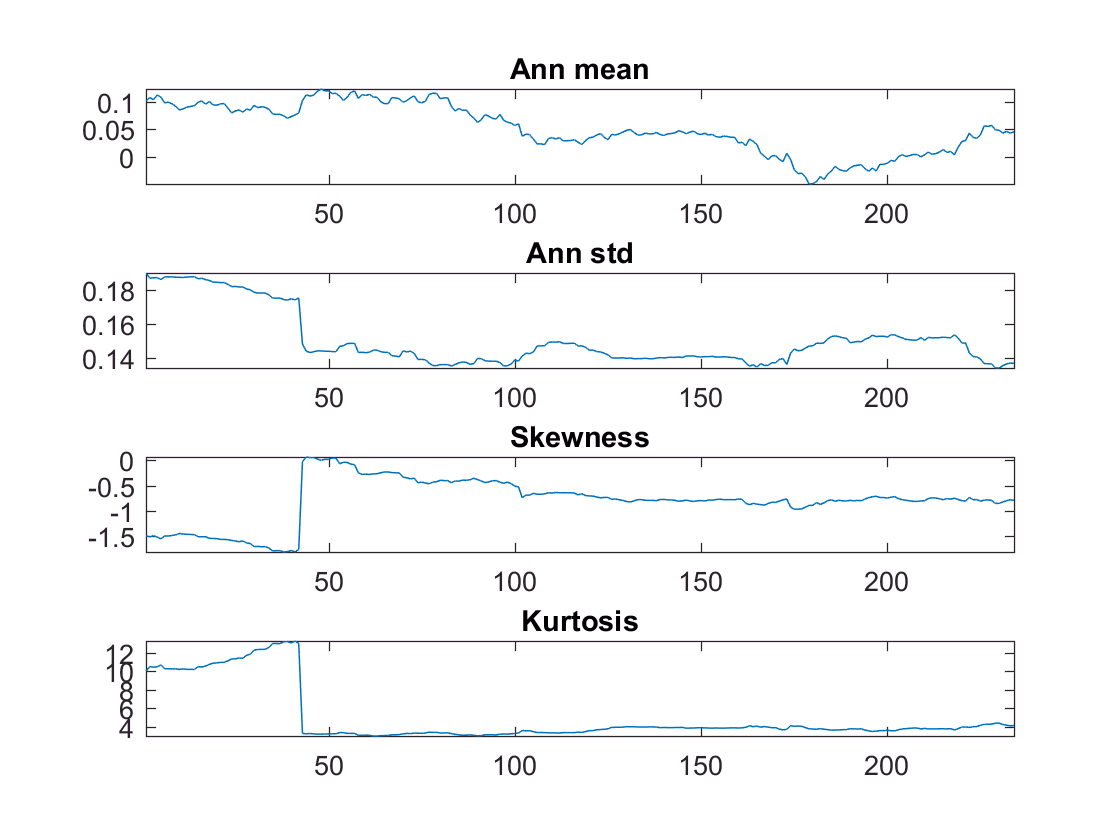

% Relabel returns so I can use r in the loop
returns = r;
% Initialize somewhere to store the estimates
mus = zeros(T-119,1);
sigma2s = zeros(T-119,1);
skewnesses = zeros(T-119,1);
kurtoses = zeros(T-119,1);
% Use a loop to estimate the parameters
for i=1:T-119
    r = returns(i:i+119);
    mus(i) = mean(r);
    sigma2s(i) = mean((r-mus(i)).^2);
    mom3 = mean((r-mus(i)).^3);
    skewnesses(i) = mom3/sigma2s(i)^(3/2);
    mom4 = mean((r-mus(i)).^4);
    kurtoses(i) = mom4/sigma2s(i)^2;
end
% Form into a matrix
titles = {'Ann mean','Ann std','Skewness','Kurtosis'};
data = [12 * mus / 100 sqrt(12*sigma2s/10000) skewnesses kurtoses];
% Open a new figure
figure(2)
% Loop over data and use subplot to graph
for i=1:4
    subplot(4,1,i)
    plot(data(:,i))
    title(titles{i});
    axis tight
end